## divide train set and test set

data = X_tsne;
label = y;

ratio = 0.8;
num_train = floor(length(label)*ratio); 
choose = randperm(length(label)); 

train_data  = data(choose(1:num_train), :);
train_label = label(choose(1:num_train));
test_data   = data(choose(num_train+1:end), :);
test_label  = label(choose(num_train+1:end));

tic
[bestacc, bestc, bestg] = svm_gridsearch(train_label,...
                        train_data,-4, 2, -4, 2, 10, 1, 1, 0.2);
toc

*
optimization finished, #iter = 79
nu = 0.958827
obj = -5.628974, rho = -0.184940
nSV = 143, nBSV = 138
*
optimization finished, #iter = 76
nu = 0.921744
obj = -5.188465, rho = -0.244468
nSV = 139, nBSV = 132
*
optimization finished, #iter = 75
nu = 0.965986
obj = -5.818656, rho = -0.184614
nSV = 143, nBSV = 139
*
optimization finished, #iter = 68
nu = 0.927195
obj = -5.380467, rho = -0.095474
nSV = 134, nBSV = 132
*
optimization finished, #iter = 71
nu = 0.972785
obj = -6.367833, rho = 0.077608
nSV = 140, nBSV = 138
*
optimization finished, #iter = 70
nu = 0.943662
obj = -5.432945, rho = 0.197900
nSV = 135, nBSV = 131
Total nSV = 282
*
optimization finished, #iter = 79
nu = 0.970862
obj = -5.718011, rho = -0.184520
nSV = 146, nBSV = 140
*
optimization finished, #iter = 79
nu = 0.907011
obj = -5.101873, rho = -0.276742
nSV = 136, nBSV = 125
*
optimization finished, #iter = 78
nu = 0.958904
obj = -5.884757, rho = -0.240175
nSV = 142, nBSV = 137
*
optimization finished, #iter = 71
nu = 

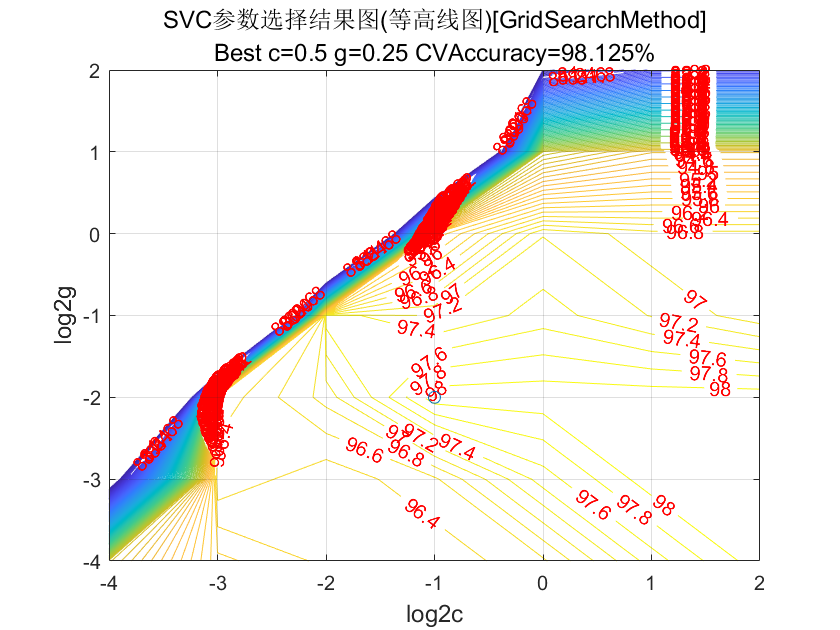

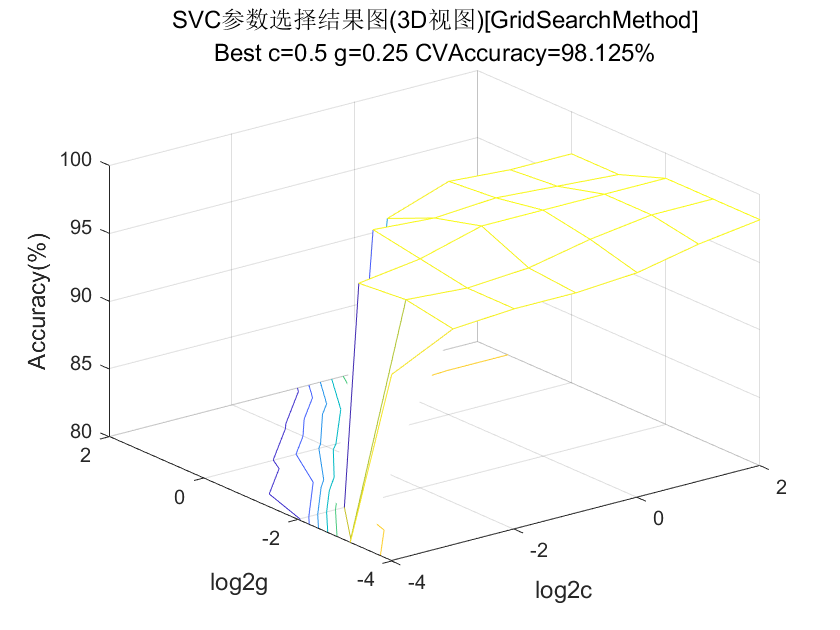

tic
[bestacc, bestc, bestg] = svm_gridsearch(train_label,...
                        train_data,0, 2, 0, 2, 10, 0.1, 0.1, 0.1);

toc

历时 3.828941 秒。


*
optimization finished, #iter = 76
nu = 0.949947
obj = -99.530997, rho = -1.906065
nSV = 142, nBSV = 140
*
optimization finished, #iter = 75
nu = 0.954207
obj = -101.322191, rho = -1.935842
nSV = 142, nBSV = 139
*
optimization finished, #iter = 72
nu = 0.965986
obj = -114.179493, rho = -1.584702
nSV = 143, nBSV = 141
*
optimization finished, #iter = 72
nu = 0.993007
obj = -105.208288, rho = -0.187946
nSV = 142, nBSV = 142
*
optimization finished, #iter = 72
nu = 0.993007
obj = -135.921932, rho = -0.082287
nSV = 142, nBSV = 142
*
optimization finished, #iter = 71
nu = 1.000000
obj = -115.866964, rho = 0.732608
nSV = 142, nBSV = 142
Total nSV = 287
*
optimization finished, #iter = 73
nu = 0.931378
obj = -98.405171, rho = -1.857350
nSV = 138, nBSV = 136
*
optimization finished, #iter = 71
nu = 0.942486
obj = -99.354360, rho = -1.956732
nSV = 138, nBSV = 136
*
optimization finished, #iter = 72
nu = 0.958904
obj = -113.087353, rho = -1.619314
nSV = 141, nBSV = 138
*
optimization finished, 

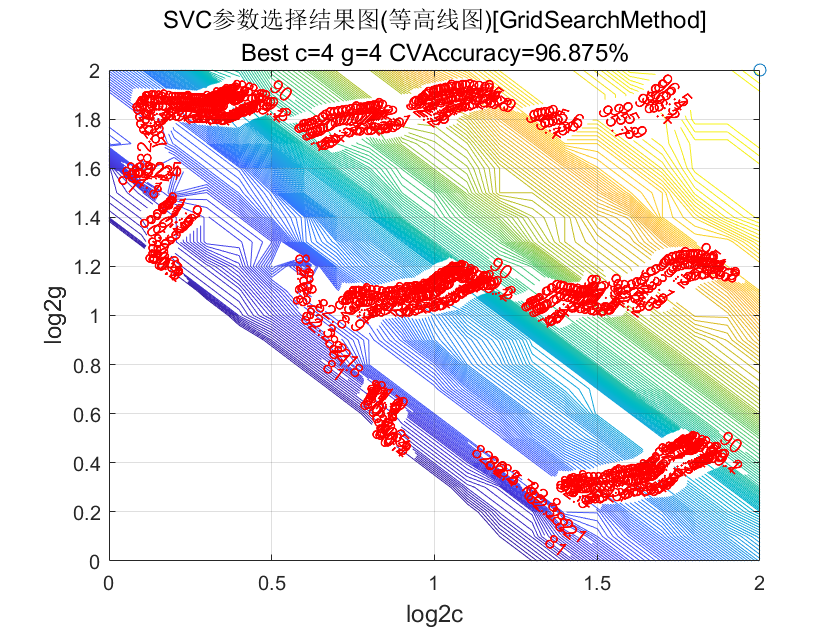

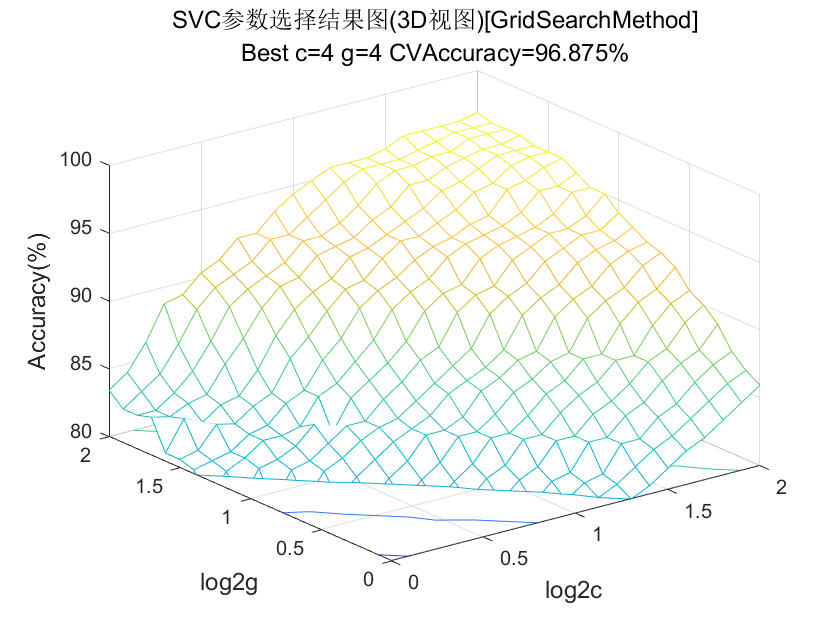

s = 0;
t = 0;
c = bestc;

g = bestg;

历时 157.120642 秒。


options = [' -s ',num2str(s),' -t ',num2str(t),' -c ',num2str(c),' -g ',num2str(g)]; 
model = libsvmtrain(train_label, train_data, options); 

[train_pred_label, train_acc, ~]...
           = libsvmpredict(train_label, train_data, model);
[test_pred_label, test_acc, ~]...
           = libsvmpredict(test_label, test_data, model);

*
optimization finished, #iter = 161
nu = 0.000399
obj = -0.016365, rho = 0.110784
nSV = 4, nBSV = 0
*
optimization finished, #iter = 154
nu = 0.005539
obj = -0.224236, rho = 3.294673
nSV = 4, nBSV = 0
*
optimization finished, #iter = 13
nu = 0.019520
obj = -0.836194, rho = 6.863520
nSV = 6, nBSV = 1
..*
optimization finished, #iter = 428
nu = 0.061471
obj = -3.765412, rho = 0.160260
nSV = 11, nBSV = 7
....
*....*
optimization finished, #iter = 1221
nu = 0.207936
obj = -16.154802, rho = 2.005242
nSV = 36, nBSV = 32
.
*.*
optimization finished, #iter = 398
nu = 0.053265
obj = -3.656991, rho = -2.076825
nSV = 11, nBSV = 7
Total nSV = 63


Accuracy = 95.3125% (305/320) (classification)


Accuracy = 91.25% (73/80) (classification)
